## **Computation Time**

clc;
clear all;
y_time_record=zeros(2,4);
 


## **Case Study: 6-bus system, 10-phase**

T=10;
N=6;

linedata=[1	2	0.0370 200
1       4       0.0160 200
2	3	0.1015 175
2	4	0.1170 175
3	6	0.0355 175
4	5	0.0370 200
5	6	0.1270 200];
M=size(linedata,1);
H= GSDF(linedata);
fmax=linedata(:,4);

bb= [0;0;0;50;0;0];

d_r=[0 50 50 150 0 75;0 60 90 180 0 70;0 30 90 190 0 72;0 50 40 150 0 77;
    0 69 105 160 0 79;0 24 57 170 0 34;0 56 76 129 0 40;0 60 90 172 0 60;
    0 50 100 176 0 65;0 30 108 134 0 80];  % concerned with T

p_raw=[1.2 0.8 0 0 1.4 1.4;2.8 1.8 0 0 2.4 2.4;4.4 2.8 0 0 2.4 2.4];
q=[0 0 0 0 0 0;-80 -50 0 0 -40 -40;-240 -150 0 0 -40 -40];

gmin=[50;50;0;0;30;25];
gmax=[250;200;0;0;80;100];

ramp_ratio=[0.6;0.7;0;0;0.5;0.6];
UR=gmax.*ramp_ratio;
DR=gmax.*ramp_ratio;

ramp_rate=0.5;
umin=-bb*ramp_rate;
umax=bb*ramp_rate;

***emission infomation***

carbon_tax=0.2;
emission_info=[2 1 0 0 0.5 0.5];
p=p_raw+emission_info*carbon_tax;

**Uncertain Part : At Bus 4 -- wind turbine**

w_loc=[4];
w_num=size(w_loc,1);
real_capacity_scale=20;
w_f= [0 0 0 30 0 0;0 0 0 10 0 0;0 0 0 15 0 0;0 0 0 20 0 0;
    0 0 0 32 0 0;0 0 0 20 0 0;0 0 0 16 0 0;0 0 0 30 0 0;
    0 0 0 10 0 0;0 0 0 20 0 0]; % concerned with T
d_f= d_r-w_f;
filename='.\data\WindGenTotalLoadYTD_2020.xls';
error_data= gen_wind_data(real_capacity_scale,filename);

epsilon=0.1;
gamma=0.4;
c_level=0.001;
% CC(Gaussian)
tStart = cputime;
gen_performance_CC_Gaussian(T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,ramp_rate,epsilon,gamma,error_data,w_loc,w_num,DR,UR);


Optimal solution found.



t_CC= cputime - tStart;
% DRO(Binomial)
tStart = cputime;
gen_performance_DRO_Binomial(T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,ramp_rate,epsilon,gamma,error_data,w_loc,w_num,DR,UR);


Optimal solution found.



t_DRO= cputime - tStart;
%clairvoyant
tStart = cputime;
MinC(T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,umin,umax,DR,UR);


Optimal solution found.



t_ori= cputime - tStart;
% SSO
tStart = cputime;
gen_SSO_average_performance(c_level,epsilon,T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,w_loc,w_num,error_data,ramp_rate,DR,UR);


Optimal solution found.



t_SSO= cputime - tStart;
y_time_record(1,:)=[t_CC,t_DRO,t_ori,t_SSO];

## Case study: IEEE 118 bus system


N=118;
T=24; % can be changed

** read the brance data of 118-bus file**

case_filename = '.\data\ieee118cdf_2.txt';
line_info = importdata(case_filename);
cols=[1 2 8];
linedata=line_info.data(:,cols);
M=size(linedata,1);
H= GSDF(linedata);
linecapacity_filename='.\data\additional-files\Lines.csv';
fmax= xlsread(linecapacity_filename, 1, 'D2:D187');

**generator data and load data (no wind)**

P_filename='.\data\IEEE118bus_data_figure.xls';
generator_info=xlsread(P_filename,1,'E2:G55');
[~,generator_type,~]=xlsread(P_filename,1,'S2:S55');
load_info=xlsread(P_filename,4,'D2:F92');
gmin=zeros(N,1);
gmax=zeros(N,1);
d_basic=zeros(1,N);
g_type=cell(N,1);
fill_no=cell(1,1);
fill_no(1,1)={'no'};
for i=1:N
    if ismember(i,generator_info(:,1))
        bus=find(generator_info(:,1)==i);
        gmin(i,1)=generator_info(bus,2);
        gmax(i,1)=generator_info(bus,3);
        g_type(i,1)=generator_type(bus,1);
    else
        g_type(i,1)=fill_no;
    end
    if ismember(i,load_info(:,1))
        bus=find(load_info(:,1)==i);
        d_basic(1,i)=load_info(bus,3);  % can be changed
    end
end

ramp_ratio=0.7;
DR=ramp_ratio*gmax;
UR=ramp_ratio*gmax;

**price (there is no need to change the optimization function)**

carbon_tax=0.2; % can be changed
[p,q]=gen_unit_price(g_type,carbon_tax); % with parameter inside, can be changed

**demand generation**

reserve=500;
% Amp_max=(sum(gmax)-reserve)/sum(d_basic);
% Amp_min=(sum(gmin)+reserve)/sum(d_basic);
Amp_max=1.6;
Amp_min=0.8;
perturbation=Amp_max-Amp_min; % can be changed
medium_value=(Amp_max+Amp_min)/2;
% rand_multiplier=(perturbation*rand(T,N)-0.5)*2;
% d_r=d_basic.*(1+rand_multiplier);
rand_multiplier=perturbation*(rand(T,1)-0.5)+medium_value;
d_r=rand_multiplier*d_basic;

**wind and uncertain variables**

w_loc=[18,24,27,31,100,82,92,54,69,104,112];
w_num=size(w_loc,2);
w_basic=zeros(1,N);
for i=1:w_num
    loc=w_loc(i);
    w_basic(1,loc)=20; 
end
w_perturbation=0.6; % can be changed
w_rand_multiplier=w_perturbation*randn(T,N);
w_f=w_basic.*(1+w_rand_multiplier);
w_f(w_f<0)=0;
d_f= d_r-w_f;
d_f(d_f<0)=0;

**error data generation**

filename='.\data\WindGenTotalLoadYTD_2020.xls';
real_capacity_scale=20;
error_data= gen_wind_data(real_capacity_scale,filename);
bb=ones(N,1)*18;
umin=-bb*ramp_rate;
umax=bb*ramp_rate;

epsilon=0.2;
gamma=0.5;
% CC(Gaussian)
tStart = cputime;
gen_performance_CC_Gaussian(T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,ramp_rate,epsilon,gamma,error_data,w_loc,w_num,DR,UR);


Optimal solution found.



t_CC= cputime - tStart;
% DRO(Binomial)
tStart = cputime;
gen_performance_DRO_Binomial(T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,ramp_rate,epsilon,gamma,error_data,w_loc,w_num,DR,UR);


Optimal solution found.



t_DRO= cputime - tStart;
%clairvoyant
tStart = cputime;
MinC(T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,umin,umax,DR,UR);


Optimal solution found.



t_ori= cputime - tStart;
% SSO
% t_SSO=2795;
tStart = cputime;
gen_SSO_average_performance(c_level,epsilon,T,N,M,bb,d_f,p,q,H,fmax,gmin,gmax,w_loc,w_num,error_data,ramp_rate,DR,UR);
t_SSO= cputime - tStart;

y_time_record(2,:)=[t_CC,t_DRO,t_ori,t_SSO];

%save('time.mat','y_time_record');

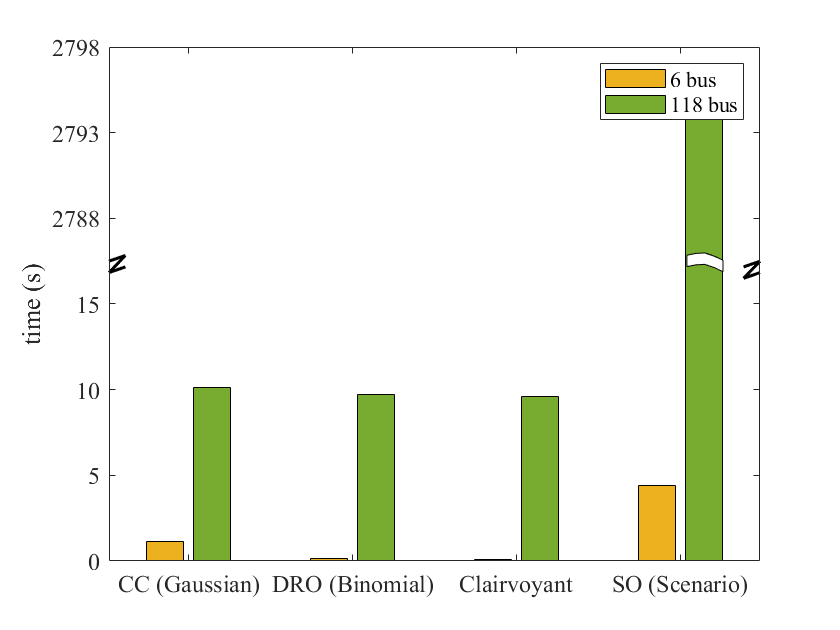

x=[1,2,3,4];
b=BarPlotBreak(x,y_time_record',15,20,'Line',0.99);
 x_label={'CC (Gaussian)','DRO (Binomial)','Clairvoyant','SO (Scenario)'};
 set(gca,'XTickLabel', x_label)
 legend('6 bus','118 bus')
 ylabel('time (s)','FontSize',13.2,'FontName','Times New Roman','FontWeight','Bold')
 set(gca,'FontSize',12,'FontName','Times New Roman')
 b(1).FaceColor=[0.9290, 0.6940, 0.1250];
 b(2).FaceColor=[0.4660, 0.6740, 0.1880];